# EFMouse: 4xLumbar with craniotomy montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 4xLumbar with craniotomy montage in: 

Sanchez-Romero R., Akyuz, S., & Krekelberg, B. (2024). EFMouse: a Matlab toolbox to model electric fields in the mouse brain. bioRxiv. https://doi.org/10.1101/2024.07.25.605227

The notebook is also an introductory tutorial to simulate other montages.

*(Developed by Ruben Sanchez-Romero and Bart Krekelberg,*

*Rutgers-Newark, Center for Molecular and Behavioral Neuroscience,*

*for support open an issue in https://github.com/klabhub/EFMouse/issues)*

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The getDP finite element method (FEM) solver (v 3.2.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations in and on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2024) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- Stage.INIT           : Initialize. 

- Stage.MESH       : Define elecrodes and (optionally) a craniotomy.

- Stage.EXPORT   : Export files for the FEM solver getDP.

- Stage.GETDP     : Run the FEM solver.

- Stage.ATLAS      : Map the results to the Allen mouse atlas.

### Stage INIT: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.ID = '4xLumbar_cran';  % A name/tag for this simulation.
o.dir = '/Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran'; % Results and the object (4xLumbar_cran.mat) will be saved here.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` o

Object contains the default mouse mesh (without stimulation electrodes). Let's visualize it.

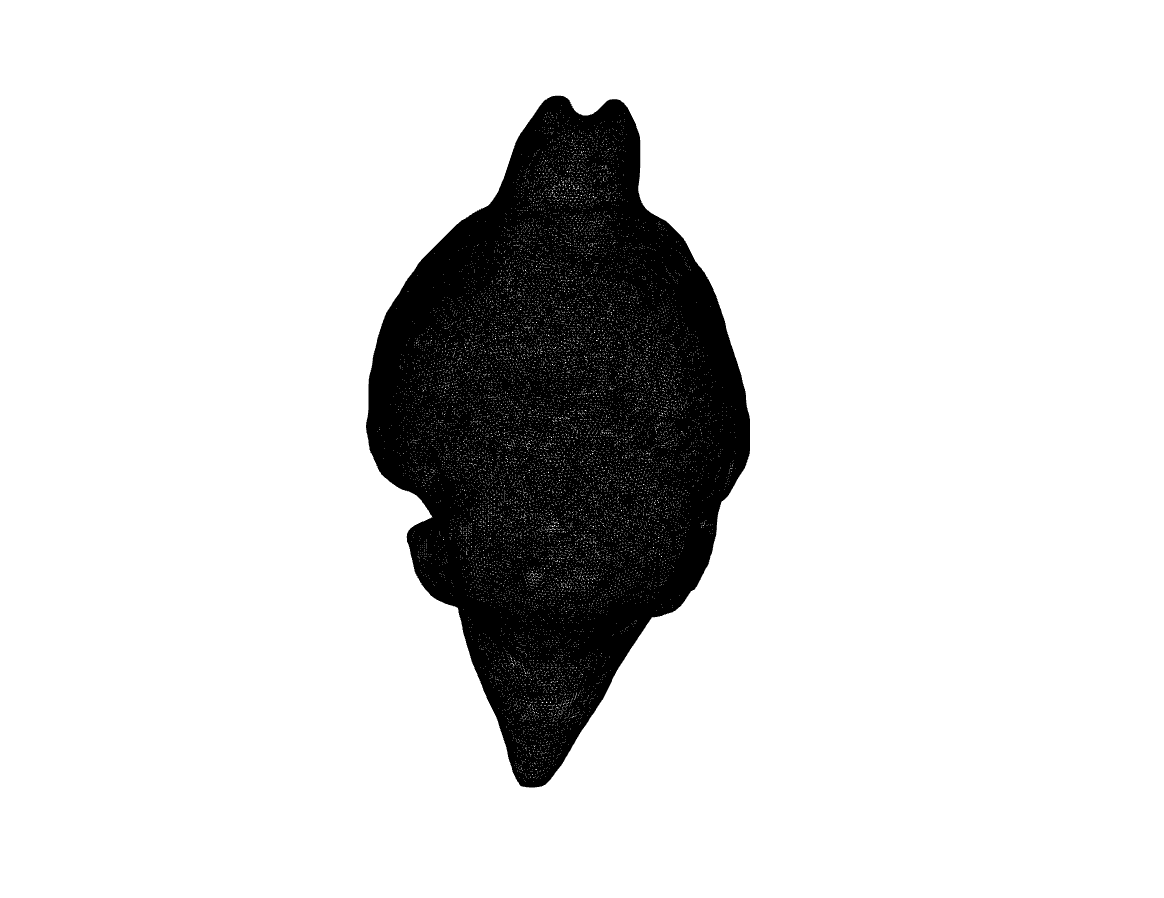

plotMesh(o,tissue="gray")

The mesh is pretty dense, so it may look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage MESH: Create electrodes and a craniotomy

Now we define a 4x1 center-surround stimulation montage, targeting visual areas.  The surface type is an electrode that is placed on top of the animal (simulating how gel would be placed on the skin).

o.addElectrode(tag = "Anterior",current = 0.05,type="surface",shape="circle",center= [-3.5,30,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Posterior",current = 0.05,type="surface",shape="circle",center= [-3.5,25,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Lateral",current = 0.05,type="surface",shape="circle",center= [-6,27.5,4],radius=0.6, thickness=1);
o.addElectrode(tag = "Medial",current = 0.05,type="surface",shape="circle",center= [-1,27.5,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Lumbar",current = -0.2,type="surface",shape="rectangle",center=[-1,-12,10],length=15,width=15,thickness=1);

Add a craniotomy between the stimulation electrodes. Select the material replacing the space where skin and bone were removed. Here, we simulate the presence of a glass coverslip that stop the csf to flow to the skin.  

o.addCraniotomy(tag = "left",center=[-3.5,27.5,6],radius=1.5,material=["air","csf"]);

To update the model with the electrodes, we run the pipeline to Stage.MESH. 

We can set show=false, and then plot using plotMesh() showing skin tissue to visualize the return electrode in the lumbar. We also adjust the ylim dimensions to visualize the whole body.

Compute stage MESH
EF Mouse Model (label: 4xLumbar_cran) in directory /Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran (stage=INIT).
-Meshing 5 electrodes-
Closest skin node is 0.7 away from the Anterior electrode target position.
Closest skin node is 0.1 away from the Posterior electrode target position.
Closest skin node is 0.6 away from the Lateral electrode target position.
Closest skin node is 0.3 away from the Medial electrode target position.
Closest skin node is 0.5 away from the Lumbar electrode target position.
Found  tet #2891752 at a distance of 0.46 from the target (label : skin)
Replacing skin with air 
Replacing bone with csf 


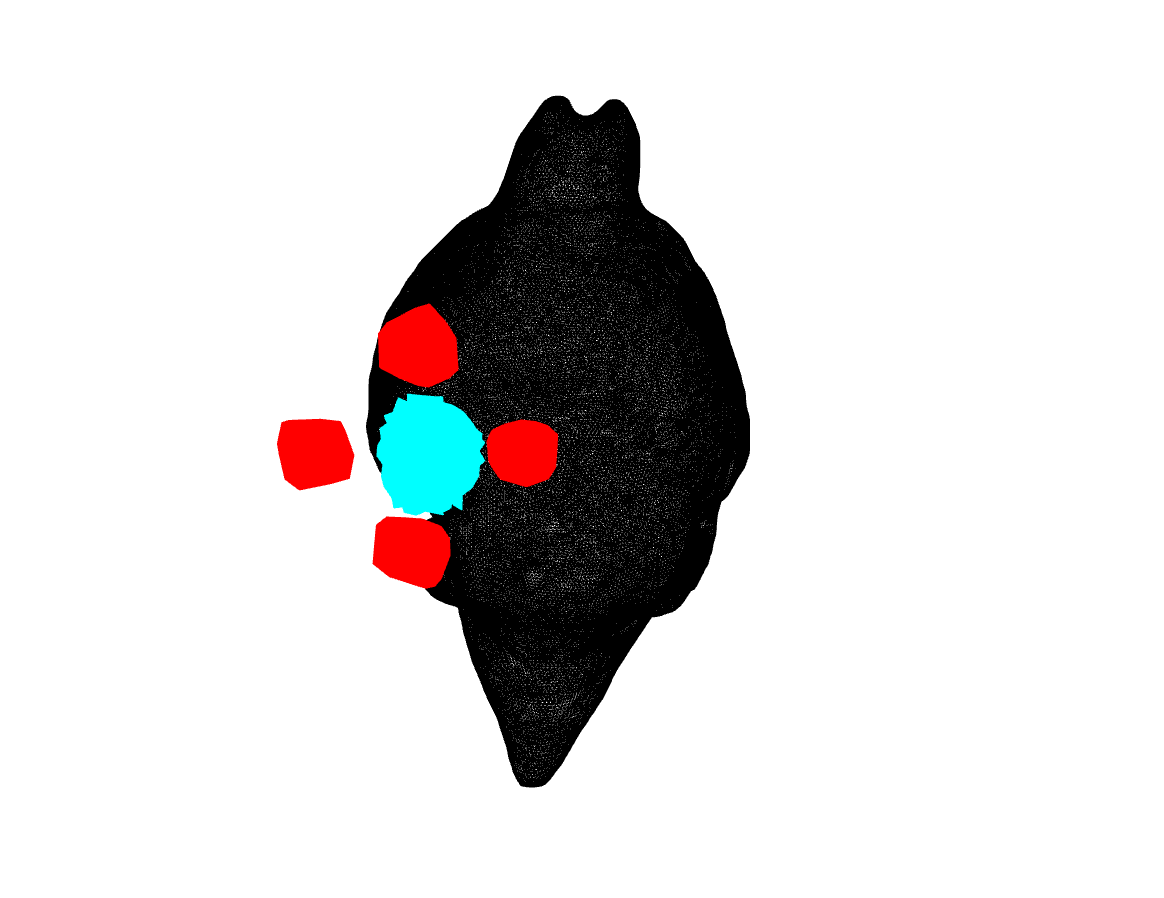

Stage MESH complete - 24.8390 seconds 


o.run(targetStage=Stage.MESH,show=true)

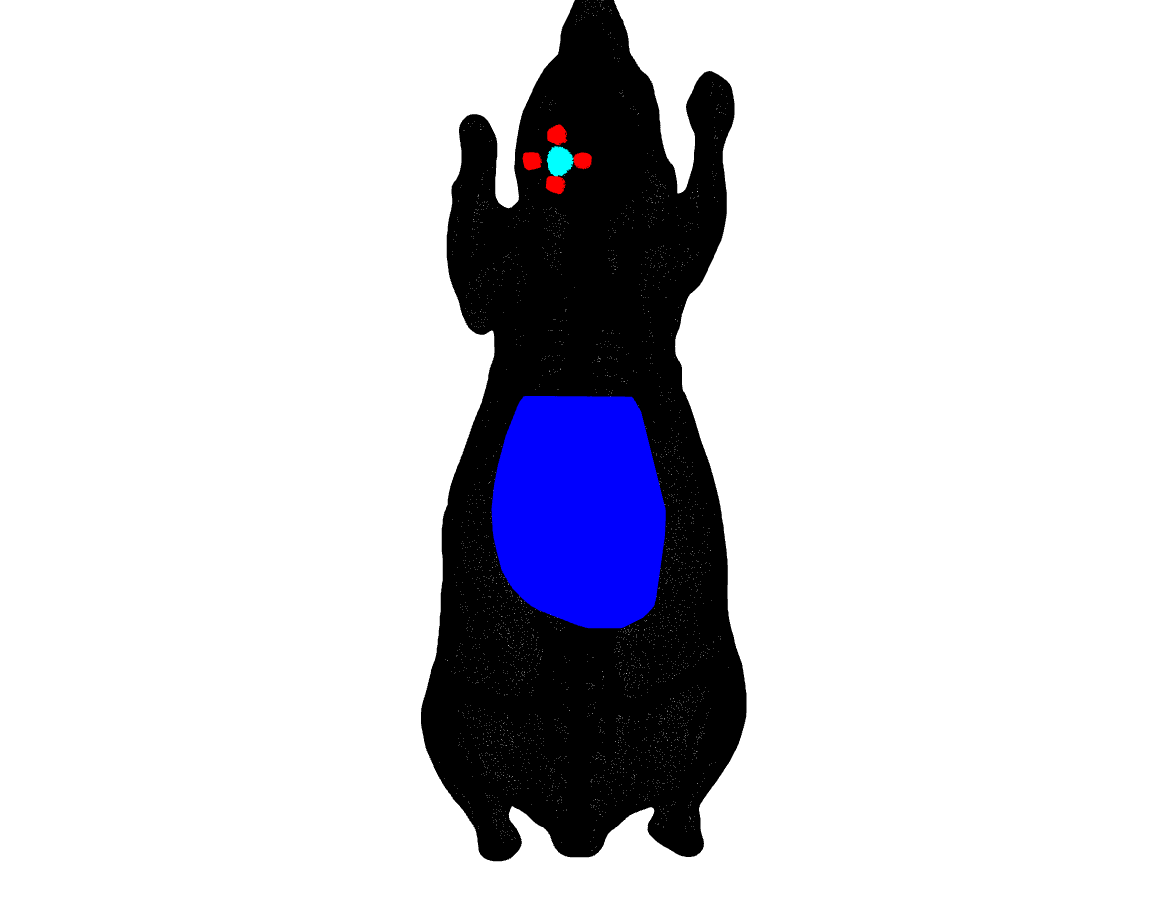

plotMesh(o,tissue="skin")
ylim([-37 37])

This mesh shows the electrodes in red (anode) and blue (cathode). For the craniotomy, the two tissue types that have been removed (skin and bone) are shown in cyan and magenta. 

### Stage EXPORT: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in 4*x1.mat*), now we export files that the FEM solver getDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells getDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=Stage.EXPORT)

Compute stage EXPORT
----Starting saveMesh...02-Jun-2025 20:04:23
----saveMesh elapsed time: 28.0371 seconds

----Starting savePro...02-Jun-2025 20:04:51
----savePro elapsed time: 0.0440 seconds

Stage EXPORT complete - 20.4677 seconds 


For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

/* 
 .pro file created by EFMouse on 02-Jun-2025 20:04:51 
 ID: 4xLumbar_cran 
 Dir: /Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
Anterior = Region[6];
Posterior = Region[7];
Lateral = Region[8];
Medial = Region[9];
Lumbar = Region[10];
leftskin = Region[11];
leftbone = Region[12];
boundaryAnterior = Region[13];
boundaryPosterior = Region[14];
boundaryLateral = Region[15];
boundaryMedial = Region[16];
boundaryLumbar = Region[17];
DomainC = Region[{gray,csf,bone,skin,eye,Anterior,Posterior,Lateral,Medial,Lumbar,leftskin,leftbone}];
AllDomain = Region[{gray,csf,bone,skin,eye,Anterior,Posterior,Lateral,Medial,Lumbar,leftskin,leftbone,boundaryAnterior,boundaryPosterior,boundaryLateral,boundaryMedial,boundaryLumbar}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[Anterior] = 0.3;
sigma[Posterior] = 0.3;
sig

This file can be opened in the getDP gui to run it manually, but Stage.GETDP runs it for you.

### Stage GETDP: run getDP

It will take getDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in getDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=Stage.GETDP,show=false);

Compute stage GETDP
Info    : Running '/Users/rubensanchez/Desktop/roast/EFmouse_class/EFMouse/lib/getdp-3.2.0/bin/getdpMac /Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran/4xLumbar_cran.pro -solve EleSta_v -msh /Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran/4xLumbar_cran.msh -pos Map' [GetDP 3.2.0, 1 node, max. 1 thread]
Info    : Started (Mon Jun  2 20:05:11 2025, Wall = 0.0981779s, CPU = 0.037894s, Mem = 5.33984Mb)
Info    : Initializing Gmsh
□□Error   : Unknown number option 'General.NativeFileChooser'□
Info    : Loading problem definition '/Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran/4xLumbar_cran.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran/4xLumbar_cran.msh'
Info    : System 'Sys_Ele' : Real
□P r e - P r o c e s s i n g . . .□
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                                          
 10%    : P

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

----Starting plotEf...02-Jun-2025 20:28:15


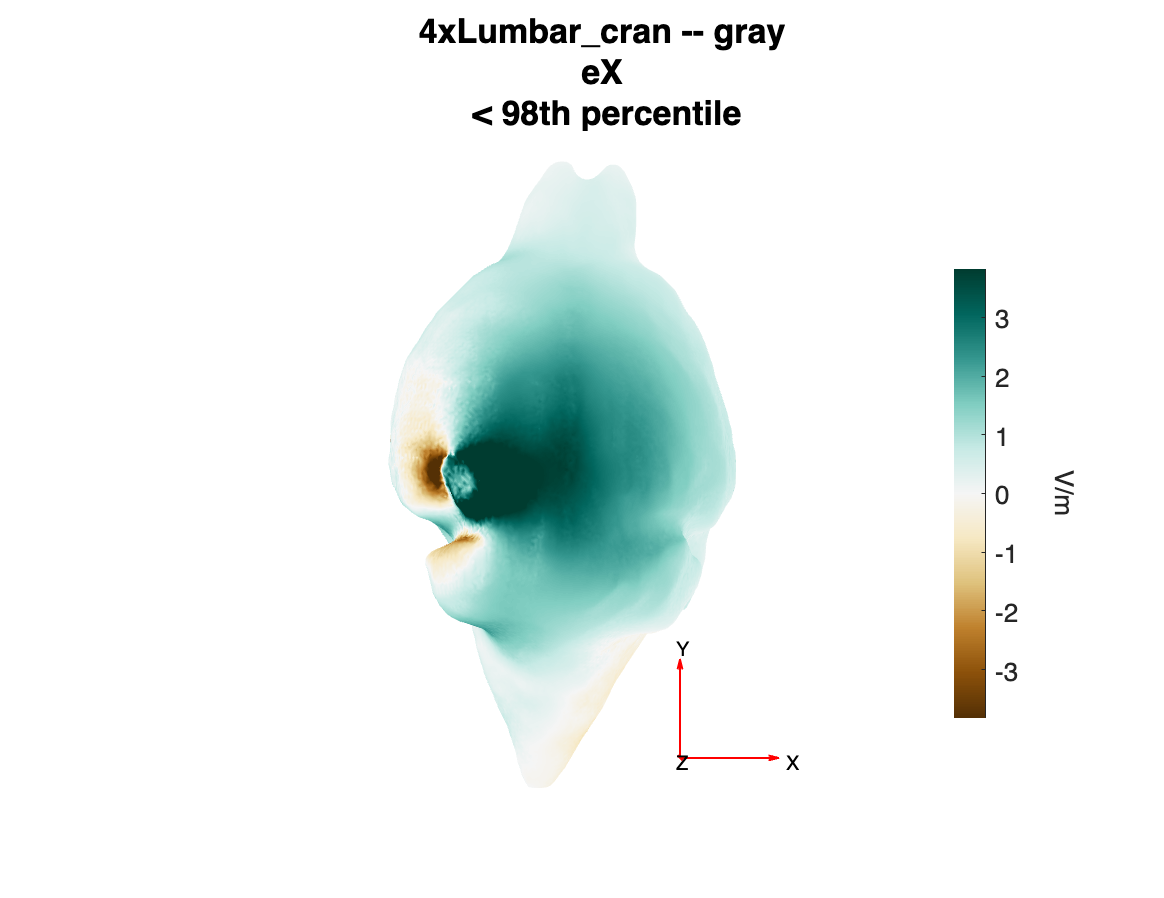

----plotEf elapsed time: 3.4908 seconds


plotEf(o,type='eX',percentile=98, tissue='gray');

----Starting plotEf...02-Jun-2025 20:28:18


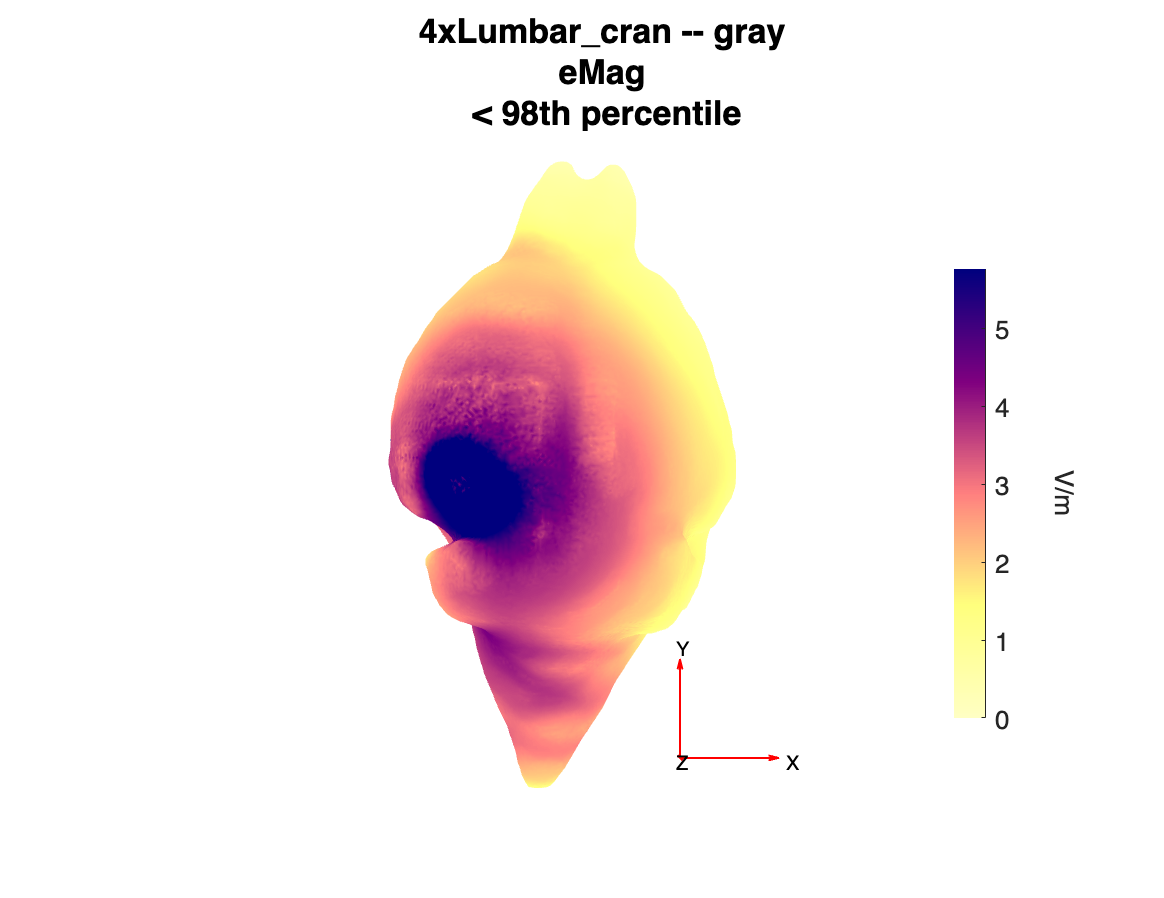

----plotEf elapsed time: 1.8906 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray')

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol. In creating the craniotomy, it was labeled after the tag chosen for the craniotomy and the name of the tissue that was removed. So `leftbone ` is the part of the mouse that was removed from the bone to create the craniotomy.

See Sanchez-Romero et al., (2024) for a full description of the electric field metrics.

analyzeTissue(o,["skin" "gray" "leftbone"])

----Starting analyzeTissue...02-Jun-2025 20:28:25
Electric field summary statistics for skin tissue
              mean       median       std         min         max  
            ________    _________    ______    __________    ______

    eX       0.24034    0.0034367    2.0477       -73.716    75.312
    eY       -1.0715     -0.57036    2.1149       -235.17    39.485
    eZ      -0.37238     0.026415     3.631       -117.42    43.323
    eMag      1.8257        1.059    4.4566    9.5191e-07    249.97

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.5920, for ef_norm_mean: (0.048 -0.565 0.171)

Electric field summary statistics for gray tissue
              mean       median      std        

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality, the reference area is the rest of the gray tissue. 

See Sanchez-Romero et al.(2014), for definitions of relative focality and homogeneity.

roi.shape = 'box';
roi.center = [-3.5 27.5 3.5];
roi.width = 2;  %Left/right
roi.length = 2; % Anterior/Posterior
roi.thickness =1;  % Z
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=75); % Define values for relative focality metric.

----Starting analyzeRoi...02-Jun-2025 20:28:30
Electric field summary statistics for a box roi in gray
             mean      median      std        min        max  
            _______    _______    ______    _______    _______

    eX      0.93514     1.0849    0.8998    -1.9584     3.2054
    eY      -1.5514    -1.4094    1.1402    -5.6484     1.0716
    eZ      -4.2185    -3.9593    1.1238    -9.1644    -2.0626
    eMag     4.7991     4.4795    1.1906     2.9239     9.3902

[Relative focality ranges from 0 to 1]
Relative focality = 0.9895, with 160508 reference nodes (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9568, for ef_norm_mean: (0.190 -0.324 -0.880)


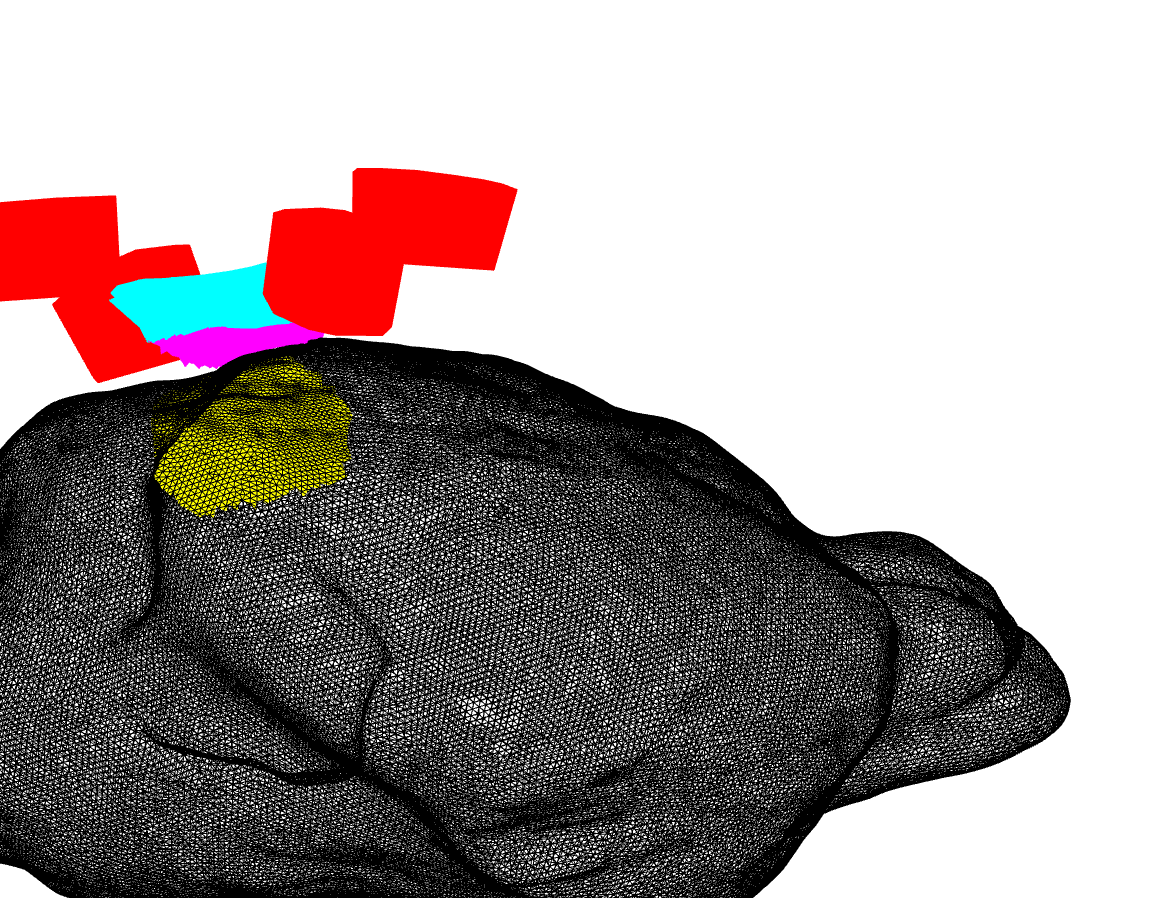

% Rotate and zoom to view the (yellow) box ROI underneath the return electrode
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an analogous box ROI but in the right hemisphere

roiRight = roi;
roiRight.center(1)  =-1* roi.center(1)

roiRight = struct with fields:
        shape: 'box'
       center: [3.5000 27.5000 3.5000]
        width: 2
       length: 2
    thickness: 1


summary = analyzeRoi(o,roiRight,plot=true,foc_percentile_max=99.9,foc_threshold=75);

----Starting analyzeRoi...02-Jun-2025 20:28:37
Electric field summary statistics for a box roi in gray
              mean       median       std        min        max   
            ________    ________    _______    _______    ________

    eX        1.2229      1.2307    0.21318    0.61778      1.7774
    eY      -0.83876    -0.80284    0.20737    -1.4759    -0.50368
    eZ       -1.0984     -1.1042    0.13541    -1.4073    -0.76341
    eMag      1.8599      1.8572    0.23003     1.3332      2.4581

[Relative focality ranges from 0 to 1]
Relative focality = 0.4081, with 160925 reference nodes (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9923, for ef_norm_mean: (0.656 -0.451 -0.59

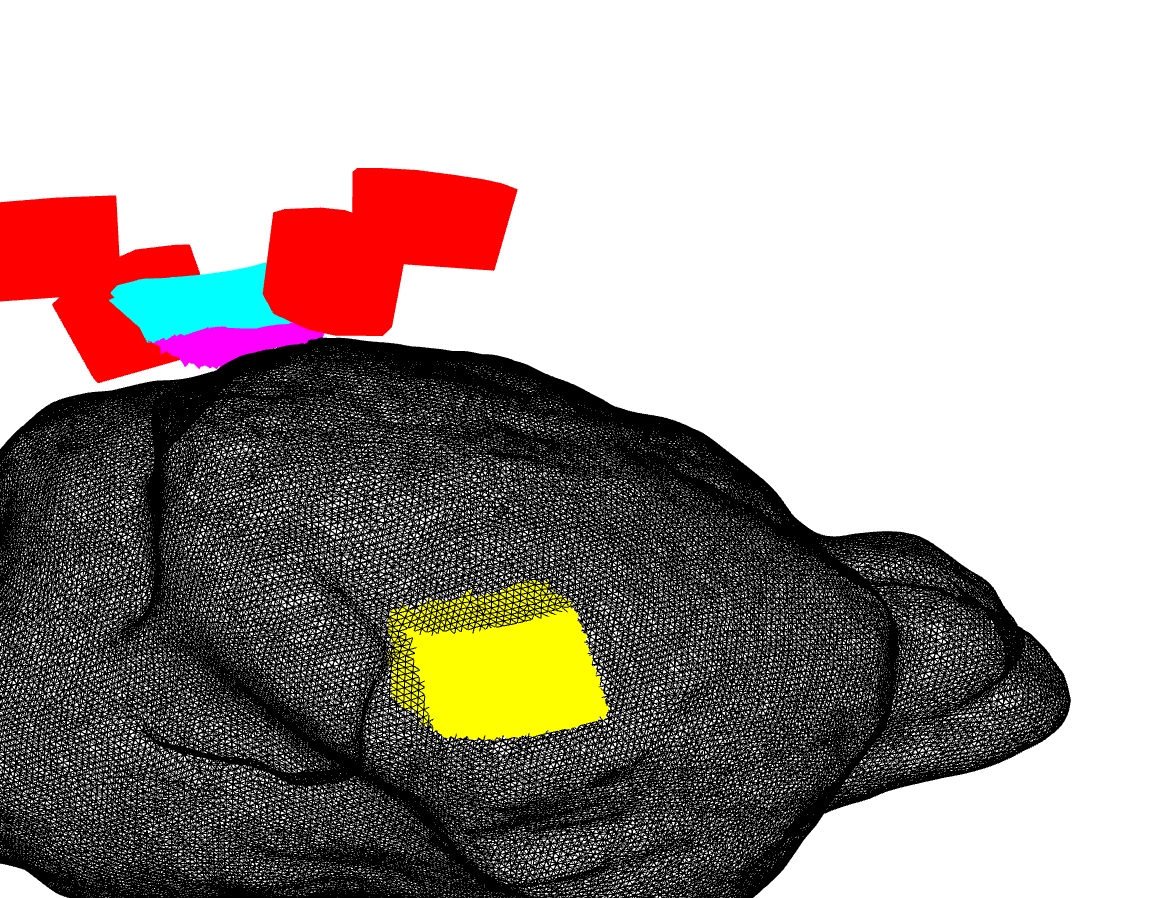

% Rotate and zoom to view the (yellow) box ROI in the right hemisphere
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage ATLAS: Volumetric/Atlas Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage ATLAS of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2014), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=Stage.ATLAS,startStage=Stage.ATLAS)

Compute stage ATLAS
----Starting computeVoxelSpace...02-Jun-2025 20:28:46
----Exporting to NIFTI volumes 
---/Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran/4xLumbar_cran_efm.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran/4xLumbar_cran_efX.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran/4xLumbar_cran_efY.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran/4xLumbar_cran_efZ.nii.gz created
----computeVoxelSpace elapsed time: 20.6261 seconds
Stage ATLAS complete - 40.4838 seconds 


### Atlas Based Analysis

Once stage ATLAS has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...02-Jun-2025 20:29:26
Area: Visual areas (1.0% of brain) , hemisphere left 
             mean      median      std         min        max  
            _______    _______    ______    _________    ______

    eX        3.413     3.9011    2.4809      -3.8185    12.218
    eY      -1.7586    -1.3411    2.3887       -10.28    6.1697
    eZ      -5.6285    -5.3291    2.7159       -13.46         0
    eMag     7.5342     7.5053    3.0121    0.0027318    15.814

[Relative focality ranges from 0 to 1]
Relative focality = 0.9997, with 92410 reference voxels (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.8931, for ef_norm_mean: (0.439 -0.237 -0.741)
----analyzeAtla

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...02-Jun-2025 20:29:27
Area: Visual areas (1.0% of brain) , hemisphere right 
             mean      median       std         min        max  
            _______    _______    _______    _________    ______

    eX       1.5508     1.6581    0.70368    0.0020031    2.7275
    eY      -1.0546    -1.1529    0.50123       -2.087         0
    eZ      -1.1659    -1.2103    0.56916      -2.1837         0
    eMag     2.2423     2.4289    0.96018    0.0027128    3.6894

[Relative focality ranges from 0 to 1]
Relative focality = 0.6496, with 92457 reference voxels (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9847, for ef_norm_mean: (0.689 -0.479 -0.515)
----anal

## Tips and Tricks

- The run function can be called with any `targetStage` from Stage.INIT to Stage.ATLAS. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial at the stage where it was last saved:

%o = EFMouse(dir='/Users/rubensanchez/desktop/efmouse_sim/4xLumbar_cran',ID='4xLumbar_cran')